# Data Reduction

clearvars
close all

A raw Shack-Hartmann spot field image of just a single megapixel contains over a million numbers. The process of reducing this massive amount of data into either a wavefront "surface" sampled over a grid of a few hundred points or a set of polynomial coefficients for a model representation is known as *data reduction*.

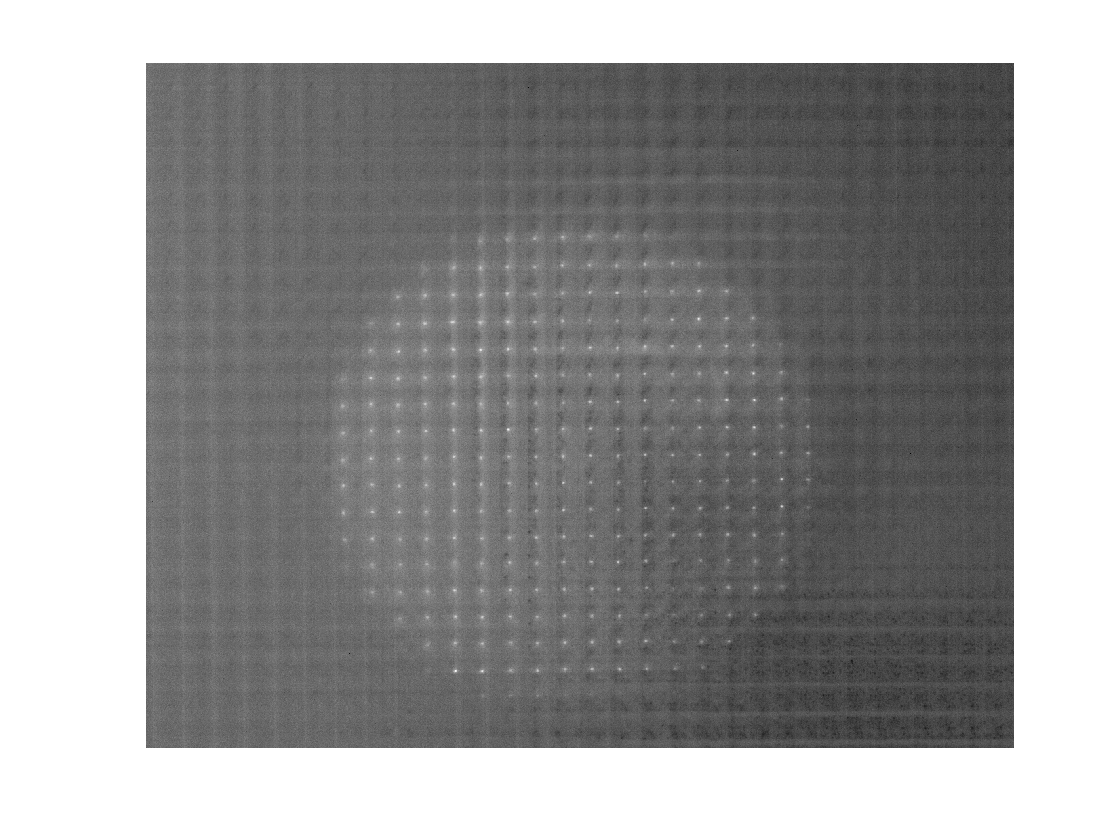

measurementFileName = "R25M0005g.tif";  

% load background and measurement images
bkgd = imread("background.tif");
meas = imread(measurementFileName);

% create Shack-Hartmann sensor model
model = Roorda(bkgd);
model.process(meas);
model.show()

%a = axes('Visible', "off");
%imshow(meas, 'initialmagnification', 75, 'parent', a, );
%imshow(meas)

%h = imshow(meas, 'initialmagnification', 75);
%axis off